T = 10e-3;

control_input = 1;

simOut_2_1_1_3_windup = sim('Lab_2\Point_2_1\2_1_1\2_1_1_3\discrete_PID_anti_windup.slx');

Found algebraic loop that contains: 
discrete_PID_anti_windup/PID/Saturation  (discontinuity)
discrete_PID_anti_windup/PID/Sum1 (algebraic variable)
discrete_PID_anti_windup/PID/Gain
discrete_PID_anti_windup/PID/Multiply
discrete_PID_anti_windup/PID/Sum2
discrete_PID_anti_windup/PID/Discrete-Time Integrator (discontinuity)


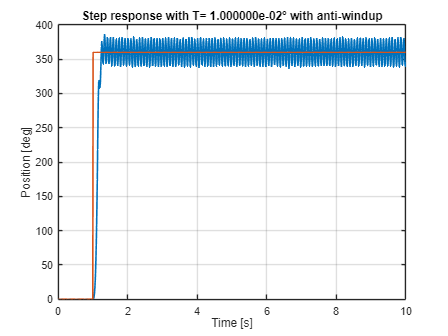


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_1_1_3_windup.theta.time,simOut_2_1_1_3_windup.theta.signals.values, 'LineWidth', 1.5);
grid on;
hold on;
plot(simOut_2_1_1_3_windup.step.time,simOut_2_1_1_3_windup.step.signals.values, 'LineWidth', 1.5);
title(sprintf('Step response with T= %d° with anti-windup', T));
xlabel('Time [s]');
ylabel('Position [deg]');

control_input = 0;

simOut_2_1_1_3_no_windup = sim('Lab_2\Point_2_1\2_1_1\2_1_1_3\discrete_PID_anti_windup.slx');

Found algebraic loop that contains: 
discrete_PID_anti_windup/PID/Saturation  (discontinuity)
discrete_PID_anti_windup/PID/Sum1 (algebraic variable)
discrete_PID_anti_windup/PID/Gain
discrete_PID_anti_windup/PID/Multiply
discrete_PID_anti_windup/PID/Sum2
discrete_PID_anti_windup/PID/Discrete-Time Integrator (discontinuity)


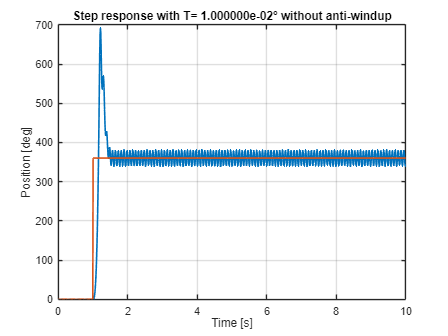


% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_1_1_3_no_windup.theta.time,simOut_2_1_1_3_no_windup.theta.signals.values, 'LineWidth', 1.5);
grid on;
hold on;
plot(simOut_2_1_1_3_no_windup.step.time,simOut_2_1_1_3_no_windup.step.signals.values, 'LineWidth', 1.5);
title(sprintf('Step response with T= %d° without anti-windup', T));
xlabel('Time [s]');
ylabel('Position [deg]');